global L d n n_a
n = 6; 
n_a = 1; n_b = n - n_a;
m = 8;
d = 3;
size = 1;
rng(3);

s = [1 1 2 2 3 3 4 5];
t = [2 4 3 5 4 6 5 6];
G = graph(s,t);
H = incidence(G)'*eye(6);
A12 = [1 0 0; 0 2 1; 0 1 2];
A25 = eye(3); A34 = A25;
A14 = [2 2 0; 2 2 0; 0 0 1];
A36 = A14;
A23 = [2 0 0; 0 0 0; 0 0 1];
A56 = A23;
A45 = [0 0 0; 0 1 0; 0 0 2];

W = blkdiag(A12,A14,A23,A25,A34,A36,A45,A56);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
x0 = [0;0;0;0;1;0;0;0;1;4*(rand(d*(n-3),1)-0.5)];
% r0 = [x0;zeros(d*(n-n_a),1)];
options = odeset('RelTol',1e-7,'AbsTol',1e-6);


## Single leader

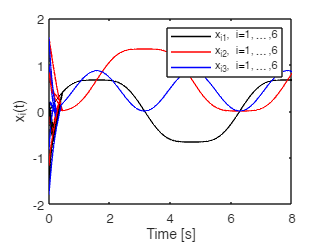


[t,r] = ode45(@smc_consensus,[0:0.01:8],x0,options);
r = r';
x = r(1:d*n,:);
eta = r(d*n+1:end,:);
Z = [zeros(n_a*d,n*d); zeros(n_b*d,n_a*d) eye(d*n_b)];
e = zeros(length(t),1);
for i=1:length(t)
    e(i,1) = norm(Z*L*x(:,i));
end

%% Plot the figures
figure
hold on;
for i=1:n
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i(t)';
box on;
legend({'x_{i1}, i=1,\ldots,6','x_{i2}, i=1,\ldots,6','x_{i3}, i=1,\ldots,6'},"NumColumns",1)

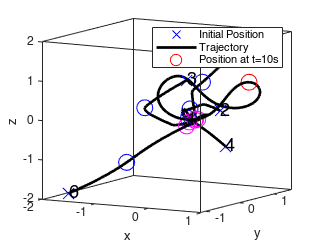


% figure
% hold on;
% for i=1:n-n_a
%    plot(t,eta(3*i-2,:),'-k','LineWidth',1);
%    plot(t,eta(3*i-1,:),'-r','LineWidth',1);
%    plot(t,eta(3*i,:),'-b','LineWidth',1);
% end
% xlabel 'Time [s]'; ylabel '\eta_i(t)';
% box on;
% legend({'\eta_{i1}, i=2,\ldots,6','\eta_{i2}, i=2,\ldots,6','\eta_{i3}, i=2,\ldots,6'},"NumColumns",1)

figure
hold on;
for i=1:n_a
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',2);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
ind1 = find(t==.1);
ind2 = find(t==.3);

for i=n_a+1:n
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',2);
   plot3(x(3*i-2,ind1),x(3*i-1,ind1),x(3*i,ind1),'ob','MarkerSize',12);
   plot3(x(3*i-2,ind2),x(3*i-1,ind2),x(3*i,ind2),'om','MarkerSize',12);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';

ax = gca;
ax.BoxStyle = 'full';
box on
legend({'Initial Position','Trajectory','Position at t=10s'}, "NumColumns", 1)
view(30,10)

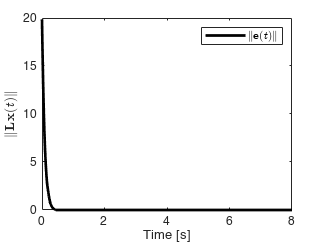


figure
hold on;
plot(t,e,'-k','LineWidth',2);
xlabel 'Time [s]'; ylabel('$\|\mathbf{L}\mathbf{x}(t)\|$', 'interpreter', 'latex');
box on;
legend({'$\|\mathbf{e}(t)\|$'}, "NumColumns", 1, 'interpreter', 'latex');

## Multiple leaders

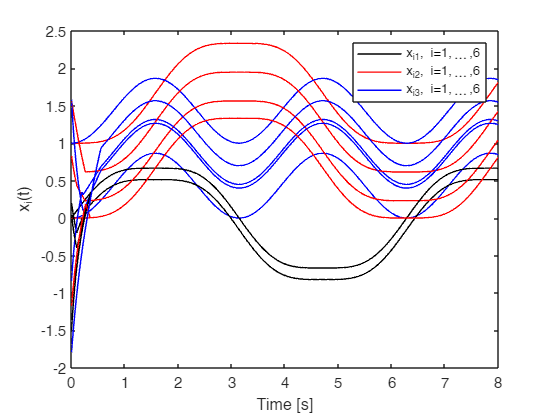

n_a = 3; n_b = n - n_a;
%r0 = [x0;zeros(d*(n-n_a),1)];
[t,r] = ode45(@smc_consensus,[0:0.01:8],x0,options);
r = r';
x = r(1:d*n,:);
%eta = r(d*n+1:end,:);
Z = [zeros(n_a*d,n*d); zeros(n_b*d,n_a*d) eye(d*n_b)];
e = zeros(length(t),1);
for i=1:length(t)
    e(i,1) = norm(Z*L*x(:,i));
end

figure
hold on;
for i=1:n
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i(t)';
box on;
legend({'x_{i1}, i=1,\ldots,6','x_{i2}, i=1,\ldots,6','x_{i3}, i=1,\ldots,6'},"NumColumns",1)

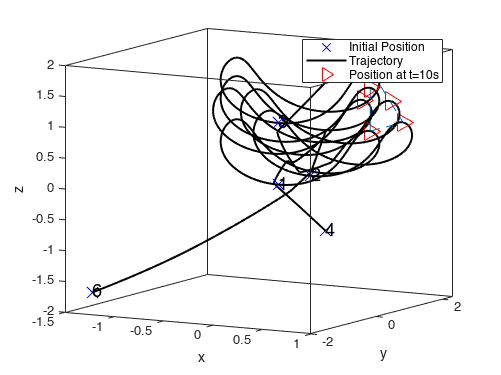


% figure
% hold on;
% for i=1:n-n_a
%    plot(t,eta(3*i-2,:),'-k','LineWidth',1);
%    plot(t,eta(3*i-1,:),'-r','LineWidth',1);
%    plot(t,eta(3*i,:),'-b','LineWidth',1);
% end
% xlabel 'Time [s]'; ylabel '\eta_i(t)';
% box on;
% legend({'\eta_{i1}, i=2,\ldots,6','\eta_{i2}, i=2,\ldots,6','\eta_{i3}, i=2,\ldots,6'},"NumColumns",1)

figure
hold on;
for i=1:n
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',1.5);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'>r','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
line([x(1,end),x(4,end)],[x(2,end),x(5,end)],[x(3,end),x(6,end)],'LineStyle','--');
line([x(1,end),x(7,end)],[x(2,end),x(8,end)],[x(3,end),x(9,end)],'LineStyle','--');
line([x(7,end),x(4,end)],[x(8,end),x(5,end)],[x(9,end),x(6,end)],'LineStyle','--');
ax = gca;
ax.BoxStyle = 'full';
box on
legend({'Initial Position','Trajectory','Position at t=10s'}, "NumColumns", 1)
view(30,10)

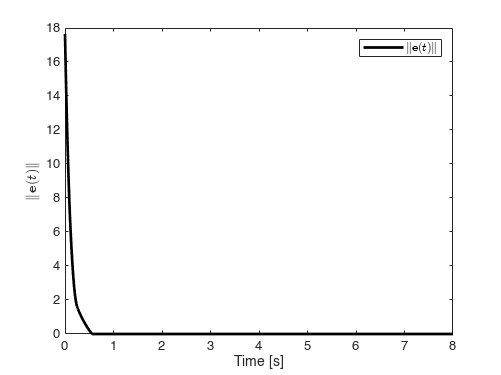


figure
hold on;
plot(t, e,'-k','LineWidth',2);
xlabel 'Time [s]'; ylabel('$\|\mathbf{e}(t)\|$', 'interpreter', 'latex');
box on;
legend({'$\|\mathbf{e}(t)\|$'}, "NumColumns", 1, 'interpreter', 'latex');

function dr = smc_consensus(t, r)
    global L d n n_a
    n_b = n - n_a;
    k_1 = 1; k_2 = 3; 
    %% Seam line of a tennis ball
%     x=cos(t).^3;
%     y=sin(t).^3;
%     z=sqrt(3)/2*sin(2*t);
% plot3(x,y,z);
% axis equal
% view(3)
% ax = gca;
% ax.BoxStyle = "full";
% box on
    v_ref = [cos(t)^3; sin(t)^3; sqrt(3)/2*sin(2*t)];
    Z = [zeros(n_a*d,n*d); 
         zeros(n_b*d,n_a*d) eye(d*n_b)];
    x = r(1:d*n,:);
%    eta = r(d*n+1:end,:);
    u = Z*(-k_1*L*x -k_2*sign(L*x)) + [kron(ones(n_a,1),v_ref); zeros(d*(n-n_a),1)];
%     ui = -k_p*Z*L*x;
%     d_eta = ui(d*n_a+1:end,:);
    dr = u; % [u; d_eta];
end